# BCI project procedure - Preprocessing (Without ICA)

**1) Rejection of bad EEG channels for each run and each subject**

For this first part, the bad EEG channels have been rejected for each run and each subject. First, it is important to select which are the subjects that are going to be used in this project among the fifteen healthy subjects that have participated in this study. On this occasion, the subjects are S1, S2, S3, S6, S7, S9, S11, S13.

It is interesting to mention that the data available for each subject consists of ten runs with 6 trials per run and the EEG signals were recorded from 61 channels covering frontal, central, parietal, and temporal areas. 

We have also chosen to show how long the calculations take, considering that the amount of data is not insignificant and thus, a good run time is desired.

subject_list= ["S1", "S2", "S3", "S6", "S7", "S9", "S11", "S13"];
addpath('functions')
waitfor(msgbox("In the next step, please select the path where eeglab is found", 'EEGLAB path selection'));
    eegpath=uigetdir;
    addpath(eegpath)
    waitfor(msgbox("Finally, please select your loc file", 'Loc file selection'));
    [locs,locpath]=uigetfile('*.loc', 'Pick a channel location file');
    locpath=strrep(locpath,'\','\\'); %for windows
    locs=append(locpath,locs);

**NOTES: **

**Make sure the folder containing your 'data' folder is added to path. **

**For further info, check each function file where the procedure will be explained in depth.**

**Please be patient. Run time with automated ICA rejection will take approximately 2-3 h on most computers.   **

## D1. Artifacted channels for each subject and run

Above, we chose our initial parameters. Now we will preprocess. The first function we call selects the bad channels for each run and saves them to a .mat file.

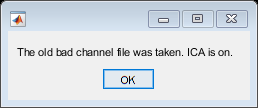

tstart=tic;
d1_bad_channels(subject_list,true,locs);

tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

Elapsed time is 0 minutes and 0.355209 seconds


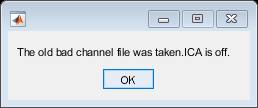

clear EEG ALLEEG CURRENTSET ALLCOM
tstart=tic;
d1_bad_channels(subject_list,false,locs);

tEnd = toc(tstart);
fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

Elapsed time is 0 minutes and 0.170057 seconds


A table has been created with the artifacted channels, the ones considered as bad channels, for each subject and run.

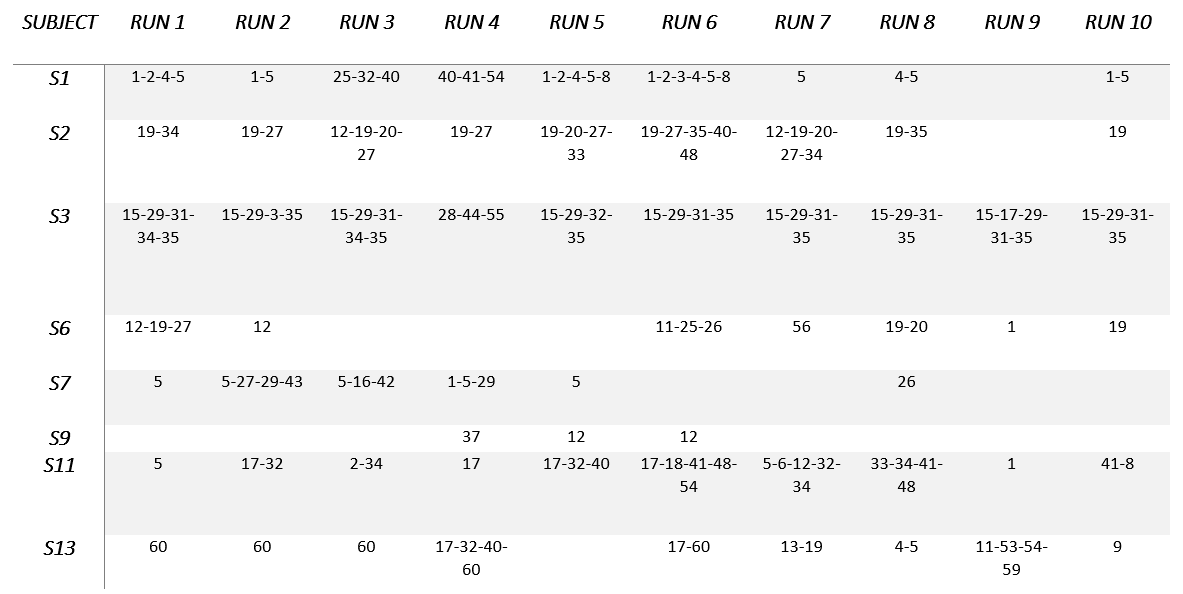

*Table 1: Bad channels witthout ICA application*

As can be observed in the table above, the channels for each run for each subject considered “bad channels” are shown. The cells with no “bad channel” are empty (-). It is important to mention that each channel has associated a label which determine the EEG electrode position. Some subjects may seem more interesting to take a second to mention on as for instance the subject number 9 which has almost no “bad channels” revealing that artifacts were not recorded. Also, subject number 3 shows some channels that are repeated in almost all the runs or a more heterogeneous distribution of bad channels during the different runs as subject 11 or subject 13. 

This time, the channels that were not eliminated for any run or subject were channels 7, 10, 14, 15, 21, 22, 23, 24, 30, 36, 38, 39, 45, 46, 47, 49, 50, 51, 52, 57, 58, and 61. 

In the table above, the bad channels resulting from the signal obtained when removing components with ICA are shown. In this first iteration, the threshold selected for component removal was too low (50% for the eye components and around 70% for the rest). A graph showing this is presented in the conclusions. Applying a such a low threshold, some of the important features of our solution get eliminated, thus directly affecting the possible analysis that can be performed. 

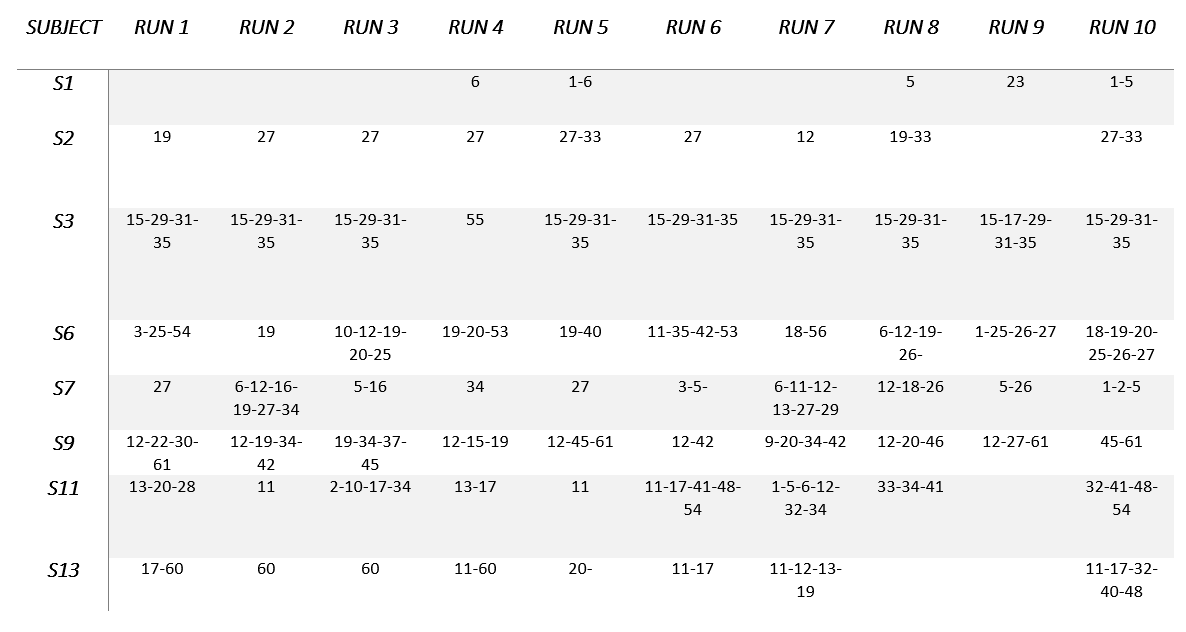

*Table 2: Bad channels with ICA, threshold for removal 50%*

It can be interesting to mention that there are some channels that have never been considered "bad channels" for any run and subject, which, more precisely, are channels 4, 7, 8, 14, 21, 24, 36, 38, 39, 43, 44, 47, 49, 50, 51, 52, 57, 58, and 59. 

In this second iteration, the threshold used for removing components with ICA was rised up until 85%. 

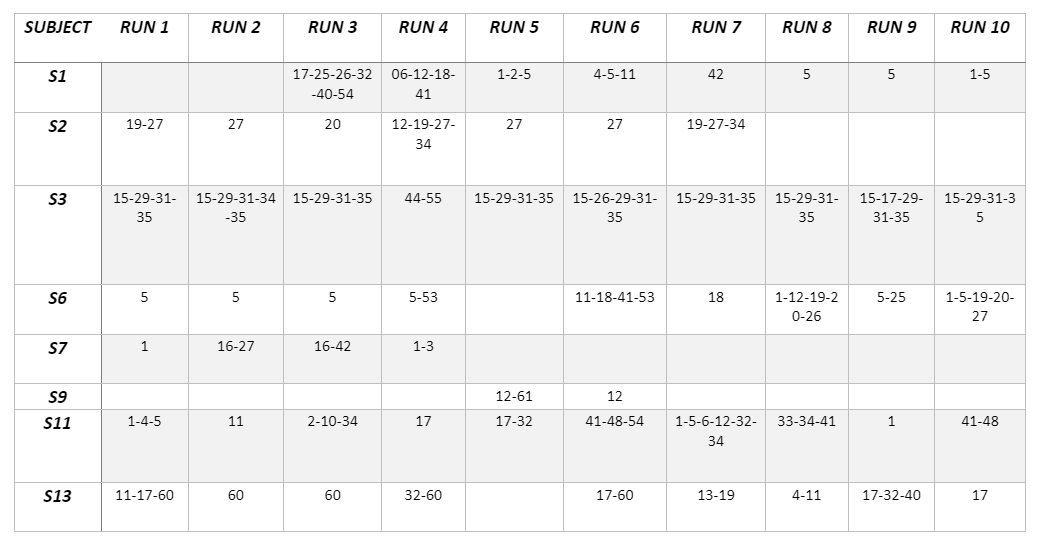

*Table 3: Bad channels with ICA, threshold for removal 85%*

It can be interesting to mention that there are some channels that have never been considered "bad channels" for any run and subject, which, more precisely, are channels 7, 8, 9, 14, 21, 22, 23, 24, 28, 30, 36, 37, 38, 39, 43, 45, 46, 47, 49, 50, 51, 52, 56, 57, 58 and 59

**2) Rejection of bad trials for each movement and subject**

Once the bad channels have been selected, we run the second function to find the bad trials. It takes the movement code as an argument, so we run it for each movement. In this case, the movement classes are:

- Flexion (1536)

- Open hand (1541)

Below, the different runs for the bad trials, with the different arguments, are coded. The variations calculated have been done with and without ICA and with and without automatic movement detection, in all of the possible permutations, thus yielding four different solutions for each movement type.

%returns the matrix, now with bad trials marked too
tstart=tic;
d2_bad_trials(subject_list,1536,true,true)
tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

Elapsed time is 0 minutes and 0.104072 seconds


tstart=tic;
d2_bad_trials(subject_list,1536,false,true)
tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

Elapsed time is 0 minutes and 0.009596 seconds



tstart=tic

tstart = uint64
741246255497

d2_bad_trials(subject_list,1536,true,false)
tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

Elapsed time is 0 minutes and 0.180015 seconds


tstart=tic;
d2_bad_trials(subject_list,1536,false,false)
tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

Elapsed time is 0 minutes and 0.007734 seconds



tstart=tic;
d2_bad_trials(subject_list,1541,true,true)
tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

Elapsed time is 0 minutes and 0.008314 seconds


tstart=tic;
d2_bad_trials(subject_list,1541,false,true)
tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

Elapsed time is 0 minutes and 0.004406 seconds



tstart=tic

tstart = uint64
741248570388

d2_bad_trials(subject_list,1541,true,false)
tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

Elapsed time is 0 minutes and 0.010675 seconds


tstart=tic;
d2_bad_trials(subject_list,1541,false,false)
tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

Elapsed time is 0 minutes and 0.007463 seconds


We have also chosen to show how long the calculations take, considering that the amount of data is not insignificant and thus, a good run time is desired.

## D2. Percentage of good (artifact-free) trials for each subject and movement class

- **Without ICA and without automatic movement detection**

Now we will want to display the data. If the variables are not loaded, we will load them from the file created in the previous step.

if exist("bad_trials_1536",'var')==0
    bad_trials_1536=load("bad_trials_1536.mat","matrix_detrend");
    bad_trials_1536=bad_trials_1536.matrix_detrend;
end
if exist("bad_trials_1541",'var')==0
    bad_trials_1541=load("bad_trials_1541.mat","matrix_detrend");
    bad_trials_1541=bad_trials_1541.matrix_detrend;
end

Next, we create a table with the percentage of good trials for all channels. Considering we saved the bad trials and runs as NaNs, the following form creates and displays a table in Matlab's table format. On this occasion, the results in the table below are considering all channels. 

%create a table of good trial percentage per user/movement
T=[];
for subject=1:length(bad_trials_1536(1,1,1,:))
        T(subject,1)=nnz(~isnan(bad_trials_1536(:,:,:,subject)))/numel(bad_trials_1536(:,:,:,subject));
        T(subject,2)=nnz(~isnan(bad_trials_1541(:,:,:,subject)))/numel(bad_trials_1541(:,:,:,subject));

end
T=round(T,4)*100;
T=array2table(T,"RowNames",subject_list,"VariableNames",["Elbow Flexion", "Hand Opening"]);
disp(T)

           Elbow Flexion    Hand Opening
           _____________    ____________

    S1         91.56           92.54    
    S2         84.02           85.85    
    S3         89.62           91.45    
    S6         88.63           88.63    
    S7         93.33           93.52    
    S9         91.42           91.83    
    S11        89.23           89.15    
    S13        93.06           82.05    



In the table above, the percentage of artifact-free trials for each subject can be seen for each movement class. Regarding elbow flexion, subject 2 is presents a lower rate of artifact-free trials, while subject 7 presents the best result. On the other hand, with regards to hand opening, subject 13 presents a lower percentage while subject 9 presents a higher percentage of artifact-free trials. 

- **With reduction of contamination by ICA**

if exist("bad_trials_1536_with_ica",'var')==0
    bad_trials_1536_with_ica=load("bad_trials_1536_with_ica.mat","matrix_detrend");
    bad_trials_1536_with_ica=bad_trials_1536_with_ica.matrix_detrend;
end
if exist("bad_trials_1541_with_ica",'var')==0
    bad_trials_1541_with_ica=load("bad_trials_1541_with_ica.mat","matrix_detrend");
    bad_trials_1541_with_ica=bad_trials_1541_with_ica.matrix_detrend;
end

%create a table of good trial percentage per user/movement
T2=[];
for subject=1:length(bad_trials_1536_with_ica(1,1,1,:))
        T2(subject,1)=nnz(~isnan(bad_trials_1536_with_ica(:,:,:,subject)))/numel(bad_trials_1536_with_ica(:,:,:,subject));
        T2(subject,2)=nnz(~isnan(bad_trials_1541_with_ica(:,:,:,subject)))/numel(bad_trials_1541_with_ica(:,:,:,subject));

end
T2=round(T2,4)*100;
T2=array2table(T2,"RowNames",subject_list,"VariableNames",["Elbow Flexion", "Hand Opening"]);
disp(T2)

           Elbow Flexion    Hand Opening
           _____________    ____________

    S1         92.54           92.19    
    S2         85.87           89.86    
    S3         87.32           92.02    
    S6         85.05           80.77    
    S7         93.06           91.39    
    S9         89.48           90.16    
    S11        91.91            89.1    
    S13        89.97           80.55    



- **With automatic detection of movement onset**

if exist("bad_trials_1536_with_auto",'var')==0
    bad_trials_1536_with_auto=load("bad_trials_1536_with_auto.mat","matrix_detrend");
    bad_trials_1536_with_auto=bad_trials_1536_with_auto.matrix_detrend;
end
if exist("bad_trials_1541_with_auto",'var')==0
    bad_trials_1541_with_auto=load("bad_trials_1541_with_auto.mat","matrix_detrend");
    bad_trials_1541_with_auto=bad_trials_1541_with_auto.matrix_detrend;
end

%create a table of good trial percentage per user/movement
T3=[];
for subject=1:length(bad_trials_1536_with_auto(1,1,1,:))
        T3(subject,1)=nnz(~isnan(bad_trials_1536_with_auto(:,:,:,subject)))/numel(bad_trials_1536_with_auto(:,:,:,subject));
        T3(subject,2)=nnz(~isnan(bad_trials_1541_with_auto(:,:,:,subject)))/numel(bad_trials_1541_with_auto(:,:,:,subject));

end
T3=round(T3,4)*100;
T3=array2table(T3,"RowNames",subject_list,"VariableNames",["Elbow Flexion", "Hand Opening"]);
disp(T3)

           Elbow Flexion    Hand Opening
           _____________    ____________

    S1         86.83           92.54    
    S2         87.16           85.87    
    S3         89.62           91.45    
    S6         88.63           88.63    
    S7         91.75           93.52    
    S9          86.5           91.83    
    S11        89.18           89.15    
    S13        93.06           82.05    



- **With automatic detection of movement onset and with reduction of contamination by ICA**

if exist("bad_trials_1536_with_ica_with_auto",'var')==0
    bad_trials_1536_with_ica_with_auto=load("bad_trials_1536_with_ica_with_auto.mat","matrix_detrend");
    bad_trials_1536_with_ica_with_auto=bad_trials_1536_with_ica_with_auto.matrix_detrend;
end
if exist("bad_trials_1541_with_ica_with_auto",'var')==0
    bad_trials_1541_with_ica_with_auto=load("bad_trials_1541_with_ica_with_auto.mat","matrix_detrend");
    bad_trials_1541_with_ica_with_auto=bad_trials_1541_with_ica_with_auto.matrix_detrend;
end

%create a table of good trial percentage per user/movement
T4=[];
for subject=1:length(bad_trials_1536_with_ica_with_auto(1,1,1,:))
        T4(subject,1)=nnz(~isnan(bad_trials_1536_with_ica_with_auto(:,:,:,subject)))/numel(bad_trials_1536_with_ica_with_auto(:,:,:,subject));
        T4(subject,2)=nnz(~isnan(bad_trials_1541_with_ica_with_auto(:,:,:,subject)))/numel(bad_trials_1541_with_ica_with_auto(:,:,:,subject));

end
T4=round(T4,4)*100;
T4=array2table(T4,"RowNames",subject_list,"VariableNames",["Elbow Flexion", "Hand Opening"]);
disp(T4)

           Elbow Flexion    Hand Opening
           _____________    ____________

    S1         87.73           92.19    
    S2         89.13           89.89    
    S3         87.32           92.02    
    S6         85.05           80.77    
    S7         91.48           91.39    
    S9         84.59           90.16    
    S11        91.89            89.1    
    S13        89.97           80.55    



Then we create a table for **Cz (channel 30)** only, in order to compare our results with the provided example.

- **Without ICA and without automatic movement detection**

T30=[];
for subject=1:length(bad_trials_1536(1,1,1,:))
        T30(subject,1)=(nnz(~isnan(bad_trials_1536(30,:,:,subject)))-(numel(bad_trials_1536(30,:,:,subject))-nnz(bad_trials_1536(30,:,:,subject))))/numel(bad_trials_1536(30,:,:,subject));
        T30(subject,2)=(nnz(~isnan(bad_trials_1541(30,:,:,subject)))-(numel(bad_trials_1541(30,:,:,subject))-nnz(bad_trials_1541(30,:,:,subject))))/numel(bad_trials_1541(30,:,:,subject));

end
T30=round(T30,4)*100;
T30=array2table(T30,"RowNames",subject_list,"VariableNames",["Elbow Flexion", "Hand Opening"]);
disp(T30)

           Elbow Flexion    Hand Opening
           _____________    ____________

    S1         96.67           96.67    
    S2         88.33           91.67    
    S3         98.33           98.33    
    S6         96.67           98.33    
    S7         96.67           96.67    
    S9         91.67           96.67    
    S11        93.33              95    
    S13        98.33           86.67    



Although for hand opening, both results are almost the same, subject 3 has a slightly higher good trial rate in the provided data. This could be due to the filtering and processing methodology, and was therefore not considered to be an issue.

- **With reduction of contamination by ICA**

T31=[];
for subject=1:length(bad_trials_1536_with_ica(1,1,1,:))
        T31(subject,1)=nnz(~isnan(bad_trials_1536_with_ica(30,:,:,subject)))/numel(bad_trials_1536_with_ica(30,:,:,subject));
        T31(subject,2)=nnz(~isnan(bad_trials_1541_with_ica(30,:,:,subject)))/numel(bad_trials_1541_with_ica(30,:,:,subject));

end
T31=round(T31,4)*100;
T31=array2table(T31,"RowNames",subject_list,"VariableNames",["Elbow Flexion", "Hand Opening"]);
disp(T31)

           Elbow Flexion    Hand Opening
           _____________    ____________

    S1         96.67              95    
    S2            90           91.67    
    S3            95           98.33    
    S6         93.33              90    
    S7         96.67              95    
    S9            90           96.67    
    S11        96.67              95    
    S13           95              85    



- **With automatic detection of movement onset**

T32=[];
for subject=1:length(bad_trials_1536_with_auto(1,1,1,:))
        T32(subject,1)=nnz(~isnan(bad_trials_1536_with_auto(30,:,:,subject)))/numel(bad_trials_1536_with_auto(30,:,:,subject));
        T32(subject,2)=nnz(~isnan(bad_trials_1541_with_auto(30,:,:,subject)))/numel(bad_trials_1541_with_auto(30,:,:,subject));

end
T32=round(T32,4)*100;
T32=array2table(T32,"RowNames",subject_list,"VariableNames",["Elbow Flexion", "Hand Opening"]);
disp(T32)

           Elbow Flexion    Hand Opening
           _____________    ____________

    S1         91.67           96.67    
    S2         91.67           91.67    
    S3         98.33           98.33    
    S6         96.67           98.33    
    S7            95           96.67    
    S9         86.67           96.67    
    S11        93.33              95    
    S13        98.33           86.67    



- **With automatic detection of movement onset and with reduction of contamination by ICA**

T33=[];
for subject=1:length(bad_trials_1536_with_ica_with_auto(1,1,1,:))
        T33(subject,1)=nnz(~isnan(bad_trials_1536_with_ica_with_auto(30,:,:,subject)))/numel(bad_trials_1536_with_ica_with_auto(30,:,:,subject));
        T33(subject,2)=nnz(~isnan(bad_trials_1541_with_ica_with_auto(30,:,:,subject)))/numel(bad_trials_1541_with_ica_with_auto(30,:,:,subject));

end
T33=round(T33,4)*100;
T33=array2table(T33,"RowNames",subject_list,"VariableNames",["Elbow Flexion", "Hand Opening"]);
disp(T33)

           Elbow Flexion    Hand Opening
           _____________    ____________

    S1         91.67              95    
    S2         93.33           91.67    
    S3            95           98.33    
    S6         93.33              90    
    S7            95              95    
    S9            85           96.67    
    S11        96.67              95    
    S13           95              85    



## D3. Plots

In this section, the average (considering only the good trials) for channel Cz for each subject and class movement has been represented. Moreover, the grand-mean average (average of all subjects) of trials for Cz and each movement class.

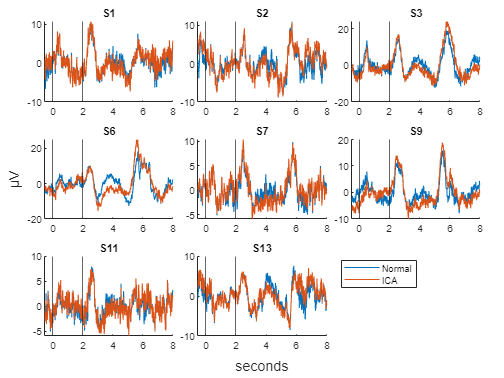

ho_30=squeeze(mean(bad_trials_1541(30,:,:,:),3,'omitnan'));
ef_30=squeeze(mean(bad_trials_1536(30,:,:,:),3,'omitnan'));

ica1536=load("bad_trials_1536_with_ica.mat");
ica1541=load("bad_trials_1541_with_ica.mat");

ho_30_ica=squeeze(mean(ica1541.matrix_detrend(30,:,:,:),3,'omitnan'));
ef_30_ica=squeeze(mean(ica1536.matrix_detrend(30,:,:,:),3,'omitnan'));
fm=512;
t=-0.5+1/fm:1/fm:(4352-0.5*512)/fm;
figure(6)
nt=tiledlayout('flow','TileSpacing','compact','Padding','compact');
for i=1:8

    nexttile
    hold on
    plot(t,ho_30(:,i))
    plot(t,ho_30_ica(:,i))  
    xline(0)
    xline(2)
    xlim([-0.5 8])
    hold off
    title(subject_list(i))

    
end
xlabel(nt,'seconds')
    ylabel(nt,'µV')
    legend('Normal','ICA',"Position",[0.67677,0.2398,0.15,0.072619])

Above, we can see that, in general, we can distinguish a relatively clear stimulus response right after the initial stimulus, followed by the reaction, which happens after 2 seconds. This is what was expected, and happens for both the ICA trated and the normally processed data. Interestingly these two are not so different, and are most clearly distinguishable in subjects that have cleaner data, such as subjects 3 and 6. We can see that the non-potential related areas are flattened by the ICA procedure.

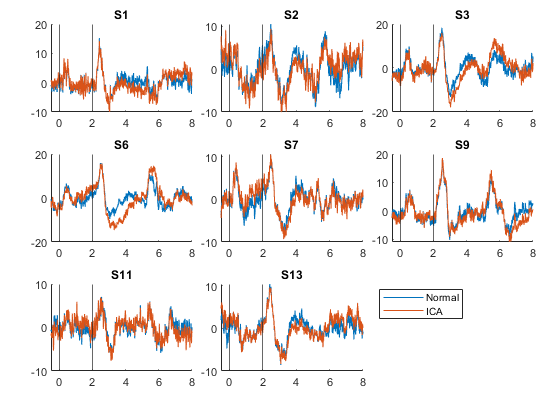

figure
t_l=tiledlayout('flow','TileSpacing','compact','Padding','compact');
for i=1:8

    nexttile
    hold on
    plot(t,ef_30(:,i))
    plot(t,ef_30_ica(:,i))
    xline(0)
    xline(2)
    xlim([-0.5 8])
    hold off
    title(subject_list(i))
    
end
xlabel(t_l,'seconds')
ylabel(t_l,'µV')
legend('Normal','ICA',"Position",[0.67677,0.2398,0.15,0.072619])

The elbow flexion movement shows no large differences when compared to hand opening movement. Perhaps, the first peak is slightly more defined while the second peak less so, but mostly, the graphs look similar. Patients 3,6 and 9 seem to have cleaner signals, indicating that perhaps, they are bald.

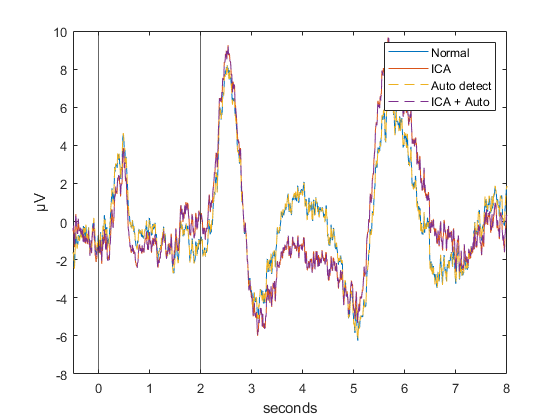

ica1536=load("bad_trials_1536_with_ica_with_auto.mat");
ica1541=load("bad_trials_1541_with_ica_with_auto.mat");

ho_30_ica_auto=squeeze(mean(ica1541.matrix_detrend(30,:,:,:),3,'omitnan'));
ef_30_ica_auto=squeeze(mean(ica1536.matrix_detrend(30,:,:,:),3,'omitnan'));

ica1536=load("bad_trials_1536_with_auto.mat");
ica1541=load("bad_trials_1541_with_auto.mat");

ho_30_auto=squeeze(mean(ica1541.matrix_detrend(30,:,:,:),3,'omitnan'));
ef_30_auto=squeeze(mean(ica1536.matrix_detrend(30,:,:,:),3,'omitnan'));

gm_average_30_ho=mean(ho_30,2);
gm_30_ica_ho=mean(ho_30_ica,2);
gm_30_ho_auto=mean(ho_30_auto,2);
gm_30_ica_auto_ho=mean(ho_30_ica_auto,2);

figure
plot(t,gm_average_30_ho)
hold on
plot(t,gm_30_ica_ho)
plot(t,gm_30_ho_auto,'--')
plot(t,gm_30_ica_auto_ho,'--')
xline(2)
xline(0)
xlim([-0.5 8])
legend('Normal','ICA','Auto detect','ICA + Auto')
xlabel('seconds')
ylabel('µV')

hold off

Above, the graph depicts the grand mean average for hand opening in all 4 evaluated variations. If the movement is automatically detected, the resulting data does not differ much from the original data. This was to be expected, since the average time difference between the provided and calculated values was in the range of 1-2ms. The resulting bad trials are thus very similar and differ only very slightly.

We can see that the grand mean average provides a clean idea of what the locked stimulus looks like. Interestingly, performing an ICA to remove undesirable components seems to affect the amplitude of the peaks and also affect how constant the other parts of the signal are.

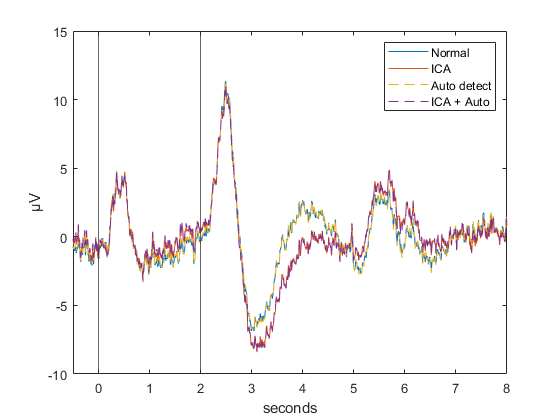

gm_average_30_ef=mean(ef_30,2);
gm_30_ica_ef=mean(ef_30_ica,2);
gm_30_ef_auto=mean(ef_30_auto,2);
gm_30_ica_auto_ef=mean(ef_30_ica_auto,2);

figure
plot(t,gm_average_30_ef)
hold on
plot(t,gm_30_ica_ef)
plot(t,gm_30_ef_auto,'--')
plot(t,gm_30_ica_auto_ef,'--')
xline(2)
xline(0)
xlim([-0.5 8])
legend('Normal','ICA','Auto detect','ICA + Auto')
xlabel('seconds')
ylabel('µV')

hold off

With the elbow flexion trial, the ICA effect becomes more clear: it is removing the baseling and is giving a signal that stays closer to average when there is no activity peak. Otherwise, there are other particularities about this grand mean average. For one, the second large peak at 6 seconds is no longer as large as the first. Also, the trough between 3 and 5 seconds has a ocmpletely different shape, which is hard to attribute to electrode placement, and might be understood as the consequence of a smaller cortical representation of the elbow in comparison to the hand, but channel 30 (Cz) is closer to this electrode. How and why this affects the signal is not clear. It might only explain why the amplitude of the elbow movement is somewhat larger.

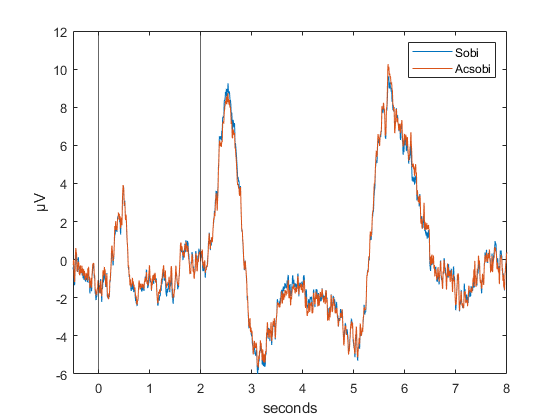

% for doing this part it is needed to have
% "bad_trials_1536_with_ica_acsobi.mat", thus the eeglab code must be
% runed with the acsobi confuguration and later on rename the variable. 

ica1536=load("bad_trials_1536_with_ica_acsobi.mat");
ica1541=load("bad_trials_1541_with_ica_acsobi.mat");

ho_30_ica_acsobi=squeeze(mean(ica1541.matrix_detrend(30,:,:,:),3,'omitnan'));
ef_30_ica_acsobi=squeeze(mean(ica1536.matrix_detrend(30,:,:,:),3,'omitnan'));

gm_30_ica_ho_acsobi=mean(ho_30_ica_acsobi,2);
gm_30_ica_ef_acsobi=mean(ef_30_ica_acsobi,2);

figure
plot(t,gm_30_ica_ho)
hold on
plot(t,gm_30_ica_ho_acsobi)
xline(2)
xline(0)
xlim([-0.5 8])
legend('Sobi','Acsobi')
xlabel('seconds')
ylabel('µV')

hold off

For the purposes of completeness, and since we have evaluated the data with both ICA decomposition types, we have decided to show the difference between the calculations made with the 'sobi' algorithm and the 'acsobiro' algorithm. Indeed, there is a difference between the two, but it is clear that it is a small difference.

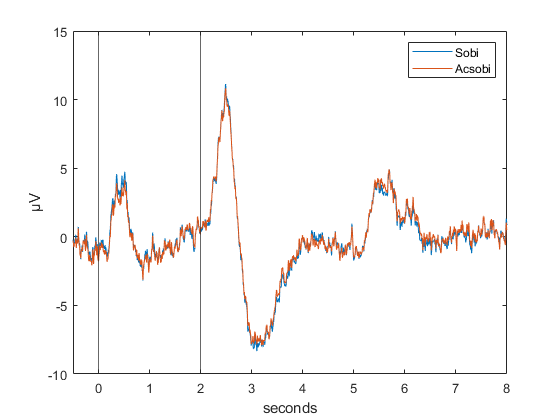

figure
plot(t,gm_30_ica_ef)
hold on
plot(t,gm_30_ica_ef_acsobi)
xline(2)
xline(0)
xlim([-0.5 8])
legend('Sobi','Acsobi')
xlabel('seconds')
ylabel('µV')

hold off

As above, we show the difference between both algorithms, this time for the elbow flexion movement.

**Conclusions**

In this preprocessing section, firstly, we have selected the bad channels by both heuristic criteria and an additional elimination of components by ICA algorithms. Then, we have proceded to select and mark the bad trials in the data, also by heuristic and statistic criteria, both with automatic movement detection as well as with the provided movement data. Finally, we have visualized the obtained data.

During this process, firstly, we looked at the signal and realized that there were multiple eye artifacts. After cleaning the signal, it had improved greatly, but the eye components were not removed effectively. On the other hand, an ICA decomposition helped with the horizontal eye movements, but was not able to separate the eye components from the brain components for blinks. Other artifacts that were removed with ICA were line noise, channel noise, muscle, heart and "other". These were only removed if the IClabel algorithm calculated that there was an 85% probability or higher that they belonged to this group. This threshold was chosen after trying a 50% for eyes and a 70% threshold for the rest of the groups. This yielded different results, which can be seen below:

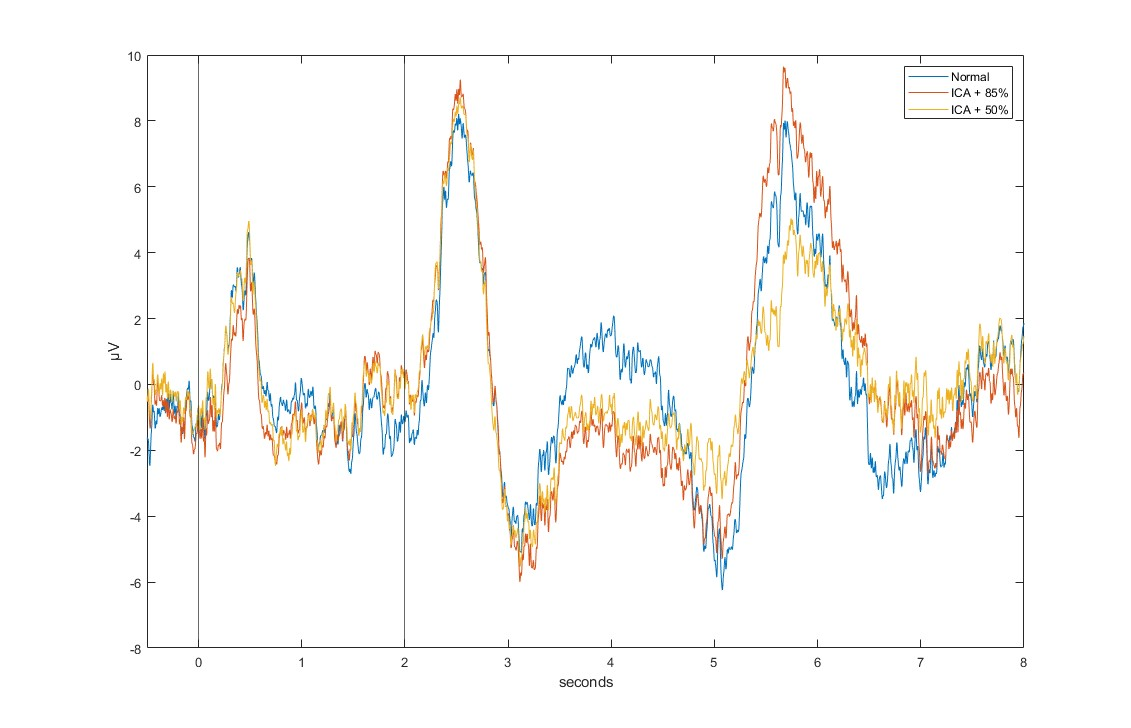

The main difference can be seen in the second peak and the trough right before it, which, when the threshold is higher, is more similar to the original signal.

The movement detection algorithm also yielded interesting results, which were corroborated manually in order to establish their accuracy. They were found to be more accurate than the provided data. Consequently, the good trial percentage differed slightly from the one we saw in the example, but was considered to be quite similar and thus satisfactory. 

Finally, the section in which we plotted the results portrayed the difficulty of visualizing differences even with large numbers of trials. It was only in the a few subjects, and especially with the grand mean average, that the general trends became more clear, and the signal became cleaner. The high variance of EEG signals, as well as the difficulty in obtaining very large datasets, makes it clear that very good signal processing is necessary in this field.

In a future version of this script, we have considered improving the way in which we save our data. Most of the run time of our script, particularly, the bad trial calculation, comes from loading very large files created in the first section. This could potentially be avoided by working with cell arrays or struct files, which would probably reduce running time by about 1 hour, by our estimations.